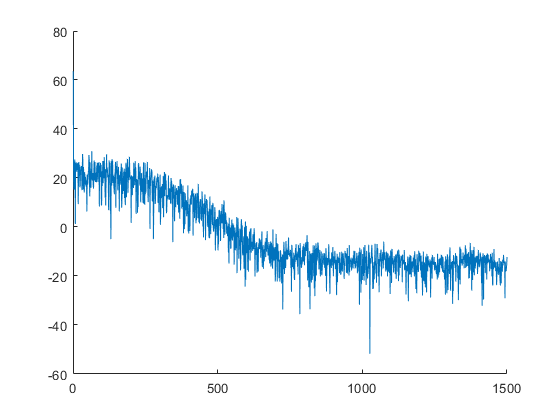

clear all
close all
clc

rng(4);

datasize = 3000;
inz = smoothdata(rand(datasize,1),'gaussian',10);


% plot(inz)

FY = mag2db(abs(fft(inz)));

figure;
hold on
plot(FY(1:floor(end/2)))
hold off


% Choose TT-ranks

n=3; m=3;
mn = n+m;

inlags=[1 2];
outlags =[0 1 2 4 8];

d=numel(inlags)+numel(outlags)-1;
% r = (min(min(mn.^[0:d],mn.^[d:-1:0]),maxrank));

synth = double(rand(mn*ones(1,d))>0.5);

% for i=1:d
% synth = (smoothdata(synth,i,'gaussian',3));
% end

TN = ttsvd(synth,0.001)

TN = struct with fields:
    core: {[1×6×6 double]  [6×6×36 double]  [36×6×195 double]  [195×6×36 double]  [36×6×6 double]  [6×6 double]}
      sz: [6×3 double]


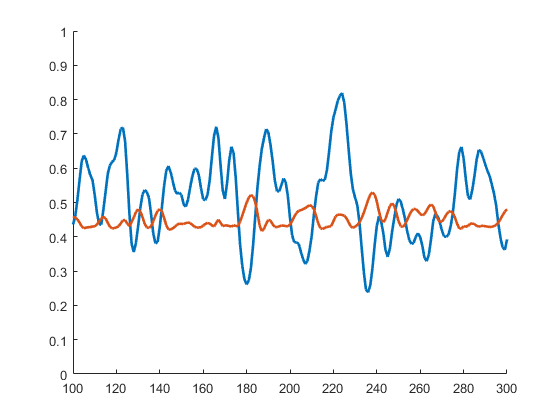


siminput = inz;
siminput(1:21)=heaviside(-10:10)/2;

simoutput = zeros(datasize,1);

% siminput = 1*ones(1000,1);
% siminput = 0.2*sin(1:0.01:11)'+0.5;

for j = 10:datasize
simfeaturez = [simoutput(j-outlags(2:end))' siminput(j-inlags(1:end))'];
% simfeaturez(simfeaturez<0)=0;
% simfeaturez(simfeaturez>1)=1;
simoutput(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
plot(siminput,'Linewidth',2)
plot(simoutput,'Linewidth',2)
% plot((inz(11)/simoutput(11))*simoutput)
hold off
axis([100 300 0 1])

noiso = 0.000001;

  
noize = noiso*randn(size(simoutput));
simoutputnoise = simoutput+ noize;
simoutputnoise(simoutputnoise>1) = 1;
simoutputnoise(simoutputnoise<0) = 0;
SNR = snr(simoutput(10:end)-mean(simoutput(10:end)),noize(10:end))

SNR = 87.4840


% figure
% hold on
% % plot(siminput)
% plot(simoutput,'Linewidth',2)
% plot(simoutputnoise)
% % plot((inz(11)/simoutput(11))*simoutput)
% hold off
% axis([0 200 -inf inf])



input = siminput(10:2000);
output = simoutputnoise(10:2000);
outputclean = simoutput(10:2000);

tinput = siminput(2001:end);
toutput = simoutput(2001:end);
toutputnoise = simoutputnoise(2001:end);


% plot(uEst)
% plot(yEst)
% for i =1:7
% uEst = [uEst ;(uEst+0.0*rand(size(uEst)))];
% yEst = [yEst ;(yEst+0.5*rand(size(yEst)))];
% end
% 
% yEst(yEst>10)=10;
% plot(uVal)
% plot(yVal)

% autocorr(uEst,1000)
% autocorr(yEst,1000)

% parcorr(uEst,1000)
% parcorr(yEst,1000)

Preprocessing Data

tic

% Choose the lags for the input
inlags=[1 2];
for l = 1:length(inlags)
u(:,l) = input(end-inlags(l)-(1900):end-inlags(l));
uv(:,l) = tinput(end-inlags(l)-(900):end-inlags(l));
end

% Choose the lags for the output, 0 is the estimated output
outlags=[0 1 2 4 8];
for l = 1:length(outlags)
y(:,l) = output(end-outlags(l)-(1900):end-outlags(l));
yv(:,l) = toutput(end-outlags(l)-(900):end-outlags(l));
end



Split test and training set

featurez = [y(:,2:end)  u];
zeta = y(:,1);

tfeaturez = [yv(:,2:end)  uv];
yt = yv(:,1);


Construct B-spline basis vectors


[N, d]=size(featurez); 

n = 3;                  %degree B-spline
m = 3;                  %Number of knot intervals
In = n+m;               %Number of B-splines

% Construct the basis vectors from the features
un = basisvectors(featurez,n,m);




Initialize tensor train -----------------------------------------------------------------


for period= 1:10
% Choose TT-ranks
maxrank =period;
r = (min(min(In.^[0:d],In.^[d:-1:0]),maxrank));

[TN,Vm,Vp] = initTT(un,r,d);


Show storage compression ratio


Pcount = (In)^d;                    %Original tensor size
dof = sum(prod(TN.sz,2));           %Degrees of freedom/ TT storage size.
disp(['Compression: ' num2str(dof/Pcount)])  %ratio

rez = [];

Compression: 0.0007716


Compression: 0.002572


Compression: 0.0054012


Compression: 0.0092593


Compression: 0.014146


Compression: 0.020062


Compression: 0.024949


Compression: 0.03035


Compression: 0.036265


Compression: 0.042695


Optimize TT cores

lambda=1*10^-4;
gamma=0;

difforder=2;
MAXITR = 4*d;


% nselect = floor(logspace(log10(dof/N),0,MAXITR)*0.5*N);


% MAXITR = d;
nselect = ones([1,MAXITR])*N;
% plot(nselect)

[TN,Vm,Vp,res1,res2] = optimTT(TN,Vm,Vp,un,zeta,MAXITR,nselect,lambda,gamma,difforder);

    "iteration:"    "1"    "0.050309"

    "iteration:"    "2"    "0.062542"

    "iteration:"    "3"    "0.06605"

    "iteration:"    "4"    "0.068659"

    "iteration:"    "5"    "0.070801"

    "iteration:"    "6"    "0.074353"

    "iteration:"    "7"    "0.076658"

    "iteration:"    "8"    "0.08122"

    "iteration:"    "9"    "0.083423"

    "iteration:"    "10"    "0.086287"

    "iteration:"    "11"    "0.089574"

    "iteration:"    "12"    "0.092071"

    "iteration:"    "13"    "0.094166"

    "iteration:"    "14"    "0.096068"

    "iteration:"    "15"    "0.098158"

    "iteration:"    "16"    "0.10014"

    "iteration:"    "17"    "0.10243"

    "iteration:"    "18"    "0.10489"

    "iteration:"    "19"    "0.10709"

    "iteration:"    "20"    "0.10933"

    "iteration:"    "21"    "0.11152"

    "iteration:"    "22"    "0.11354"

    "iteration:"    "23"    "0.11549"

    "iteration:"    "24"    "0.11744"



    "iteration:"    "1"    "0.030586"

    "iteration:"    "2"    "0.041655"

    "iteration:"    "3"    "0.047169"

    "iteration:"    "4"    "0.052505"

    "iteration:"    "5"    "0.056827"

    "iteration:"    "6"    "0.059924"

    "iteration:"    "7"    "0.062895"

    "iteration:"    "8"    "0.067389"

    "iteration:"    "9"    "0.070574"

    "iteration:"    "10"    "0.074249"

    "iteration:"    "11"    "0.13321"

    "iteration:"    "12"    "0.13934"

    "iteration:"    "13"    "0.14245"

    "iteration:"    "14"    "0.14552"

    "iteration:"    "15"    "0.14963"

    "iteration:"    "16"    "0.15362"

    "iteration:"    "17"    "0.15669"

    "iteration:"    "18"    "0.16085"

    "iteration:"    "19"    "0.17067"

    "iteration:"    "20"    "0.1792"

    "iteration:"    "21"    "0.18761"

    "iteration:"    "22"    "0.1987"

    "iteration:"    "23"    "0.208"

    "iteration:"    "24"    "0.21375"



    "iteration:"    "1"    "0.011477"

    "iteration:"    "2"    "0.023745"

    "iteration:"    "3"    "0.032597"

    "iteration:"    "4"    "0.043696"

    "iteration:"    "5"    "0.05189"

    "iteration:"    "6"    "0.057195"

    "iteration:"    "7"    "0.062243"

    "iteration:"    "8"    "0.068925"

    "iteration:"    "9"    "0.073949"

    "iteration:"    "10"    "0.080578"

    "iteration:"    "11"    "0.087553"

    "iteration:"    "12"    "0.093342"

    "iteration:"    "13"    "0.099174"

    "iteration:"    "14"    "0.10606"

    "iteration:"    "15"    "0.11366"

    "iteration:"    "16"    "0.11854"

    "iteration:"    "17"    "0.12525"

    "iteration:"    "18"    "0.13493"

    "iteration:"    "19"    "0.14668"

    "iteration:"    "20"    "0.15618"

    "iteration:"    "21"    "0.16967"

    "iteration:"    "22"    "0.17847"

    "iteration:"    "23"    "0.18803"

    "iteration:"    "24"    "0.19569"



    "iteration:"    "1"    "0.015508"

    "iteration:"    "2"    "0.037466"

    "iteration:"    "3"    "0.059804"

    "iteration:"    "4"    "0.089011"

    "iteration:"    "5"    "0.11074"

    "iteration:"    "6"    "0.13211"

    "iteration:"    "7"    "0.15001"

    "iteration:"    "8"    "0.16615"

    "iteration:"    "9"    "0.18338"

    "iteration:"    "10"    "0.20138"

    "iteration:"    "11"    "0.21987"

    "iteration:"    "12"    "0.23616"

    "iteration:"    "13"    "0.25568"

    "iteration:"    "14"    "0.27379"

    "iteration:"    "15"    "0.29046"

    "iteration:"    "16"    "0.30903"

    "iteration:"    "17"    "0.32779"

    "iteration:"    "18"    "0.34388"

    "iteration:"    "19"    "0.3692"

    "iteration:"    "20"    "0.41119"

    "iteration:"    "21"    "0.45882"

    "iteration:"    "22"    "0.47872"

    "iteration:"    "23"    "0.49568"

    "iteration:"    "24"    "0.51265"



    "iteration:"    "1"    "0.035025"

    "iteration:"    "2"    "0.060755"

    "iteration:"    "3"    "0.086508"

    "iteration:"    "4"    "0.1816"

    "iteration:"    "5"    "0.22973"

    "iteration:"    "6"    "0.25867"

    "iteration:"    "7"    "0.29265"

    "iteration:"    "8"    "0.32387"

    "iteration:"    "9"    "0.36039"

    "iteration:"    "10"    "0.38534"

    "iteration:"    "11"    "0.40878"

    "iteration:"    "12"    "0.42961"

    "iteration:"    "13"    "0.45684"

    "iteration:"    "14"    "0.48034"

    "iteration:"    "15"    "0.50062"

    "iteration:"    "16"    "0.52386"

    "iteration:"    "17"    "0.54602"

    "iteration:"    "18"    "0.57326"

    "iteration:"    "19"    "0.60314"

    "iteration:"    "20"    "0.62448"

    "iteration:"    "21"    "0.65591"

    "iteration:"    "22"    "0.68912"

    "iteration:"    "23"    "0.71495"

    "iteration:"    "24"    "0.73556"



    "iteration:"    "1"    "0.048182"

    "iteration:"    "2"    "0.088924"

    "iteration:"    "3"    "0.13297"

    "iteration:"    "4"    "0.19184"

    "iteration:"    "5"    "0.24688"

    "iteration:"    "6"    "0.29611"

    "iteration:"    "7"    "0.33731"

    "iteration:"    "8"    "0.37772"

    "iteration:"    "9"    "0.41473"

    "iteration:"    "10"    "0.4532"

    "iteration:"    "11"    "0.49536"

    "iteration:"    "12"    "0.5316"

    "iteration:"    "13"    "0.5697"

    "iteration:"    "14"    "0.61274"

    "iteration:"    "15"    "0.65288"

    "iteration:"    "16"    "0.69716"

    "iteration:"    "17"    "0.74021"

    "iteration:"    "18"    "0.77731"

    "iteration:"    "19"    "0.81634"

    "iteration:"    "20"    "0.85779"

    "iteration:"    "21"    "0.89444"

    "iteration:"    "22"    "0.93245"

    "iteration:"    "23"    "0.97378"

    "iteration:"    "24"    "1.0126"



    "iteration:"    "1"    "0.070852"

    "iteration:"    "2"    "0.13006"

    "iteration:"    "3"    "0.18888"

    "iteration:"    "4"    "0.25139"

    "iteration:"    "5"    "0.30597"

    "iteration:"    "6"    "0.36736"

    "iteration:"    "7"    "0.42717"

    "iteration:"    "8"    "0.48608"

    "iteration:"    "9"    "0.54081"

    "iteration:"    "10"    "0.59899"

    "iteration:"    "11"    "0.65498"

    "iteration:"    "12"    "0.71403"

    "iteration:"    "13"    "0.7753"

    "iteration:"    "14"    "0.8416"

    "iteration:"    "15"    "0.90952"

    "iteration:"    "16"    "0.97458"

    "iteration:"    "17"    "1.0421"

    "iteration:"    "18"    "1.1132"

    "iteration:"    "19"    "1.1792"

    "iteration:"    "20"    "1.2429"

    "iteration:"    "21"    "1.3025"

    "iteration:"    "22"    "1.3636"

    "iteration:"    "23"    "1.4267"

    "iteration:"    "24"    "1.4895"



    "iteration:"    "1"    "0.11205"

    "iteration:"    "2"    "0.21326"

    "iteration:"    "3"    "0.29687"

    "iteration:"    "4"    "0.3927"

    "iteration:"    "5"    "0.47828"

    "iteration:"    "6"    "0.57495"

    "iteration:"    "7"    "0.65998"

    "iteration:"    "8"    "0.75745"

    "iteration:"    "9"    "0.84204"

    "iteration:"    "10"    "0.93823"

    "iteration:"    "11"    "1.0228"

    "iteration:"    "12"    "1.1185"

    "iteration:"    "13"    "1.2094"

    "iteration:"    "14"    "1.3063"

    "iteration:"    "15"    "1.3933"

    "iteration:"    "16"    "1.4897"

    "iteration:"    "17"    "1.5785"

    "iteration:"    "18"    "1.675"

    "iteration:"    "19"    "1.7667"

    "iteration:"    "20"    "1.8617"

    "iteration:"    "21"    "1.9505"

    "iteration:"    "22"    "2.048"

    "iteration:"    "23"    "2.146"

    "iteration:"    "24"    "2.2634"



    "iteration:"    "1"    "0.17869"

    "iteration:"    "2"    "0.32051"

    "iteration:"    "3"    "0.47144"

    "iteration:"    "4"    "0.6073"

    "iteration:"    "5"    "0.74248"

    "iteration:"    "6"    "0.87421"

    "iteration:"    "7"    "1.0089"

    "iteration:"    "8"    "1.1421"

    "iteration:"    "9"    "1.3087"

    "iteration:"    "10"    "1.4585"

    "iteration:"    "11"    "1.607"

    "iteration:"    "12"    "1.7378"

    "iteration:"    "13"    "1.8705"

    "iteration:"    "14"    "2.0083"

    "iteration:"    "15"    "2.1434"

    "iteration:"    "16"    "2.2786"

    "iteration:"    "17"    "2.4131"

    "iteration:"    "18"    "2.5488"

    "iteration:"    "19"    "2.6851"

    "iteration:"    "20"    "2.8228"

    "iteration:"    "21"    "2.9623"

    "iteration:"    "22"    "3.1014"

    "iteration:"    "23"    "3.2377"

    "iteration:"    "24"    "3.3793"



    "iteration:"    "1"    "0.21089"

    "iteration:"    "2"    "0.39597"

    "iteration:"    "3"    "0.5815"

    "iteration:"    "4"    "0.78726"

    "iteration:"    "5"    "0.98167"

    "iteration:"    "6"    "1.1825"

    "iteration:"    "7"    "1.3889"

    "iteration:"    "8"    "1.5838"

    "iteration:"    "9"    "1.8232"

    "iteration:"    "10"    "2.0232"

    "iteration:"    "11"    "2.2268"

    "iteration:"    "12"    "2.4257"

    "iteration:"    "13"    "2.6298"

    "iteration:"    "14"    "2.825"

    "iteration:"    "15"    "3.023"

    "iteration:"    "16"    "3.2134"

    "iteration:"    "17"    "3.4184"

    "iteration:"    "18"    "3.6336"

    "iteration:"    "19"    "3.8295"

    "iteration:"    "20"    "4.0316"

    "iteration:"    "21"    "4.2235"

    "iteration:"    "22"    "4.4233"

    "iteration:"    "23"    "4.6124"

    "iteration:"    "24"    "4.8051"



rez = [rez res1];
% 
% plot(res1)
% plot(res2)
% 
% trainerror = res1(end)

% plot(rez)

Evaluate Test data

% 
% yhattrain  = evalspline(TN,featurez,n,m);
% 
% figure;
% hold on
% % plot(zeta)
% plot(outputclean(end-1900:end))
% plot(yhattrain)
% hold off
% axis([0 inf -inf inf]);
% 
% erboiz = (yhattrain-zeta);
% VAF = 1-var(erboiz)/var(zeta)
% MSE = immse(yhattrain,zeta)



% 
% yhat = evalspline(TN,tfeaturez,n,m);
% erboi = (yhat-yt);
% % histogram((erboi)');
% VAF = 1-var(erboi)/var(yt)
% MSE = immse(yhat,yt)
% 
% figure
% hold on
% plot(yt)
% plot(yhat)
% hold off
% axis([0 inf -inf inf])
% 
% %  Visualize errors
% [sortout,Iss]=sort(yhat);
% figure
% hold on
% plot(yt(Iss))
% plot(sortout,'Linewidth',3)
% hold off
% 
% FY = mag2db(abs(fft(yhat)));
% FZ = mag2db(abs(fft(yt)));
% 
% figure;
% hold on
% plot(FZ(1:floor(end/2)))
% plot(FY(1:floor(end/2)))
% hold off


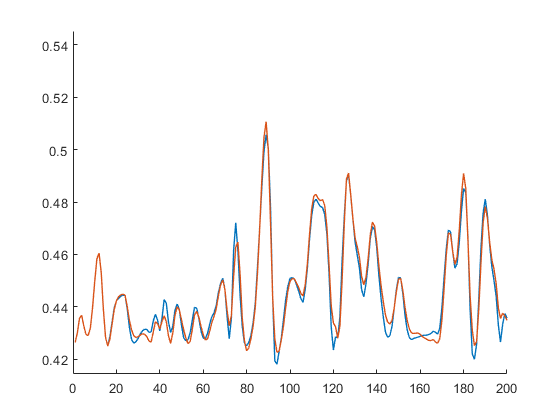

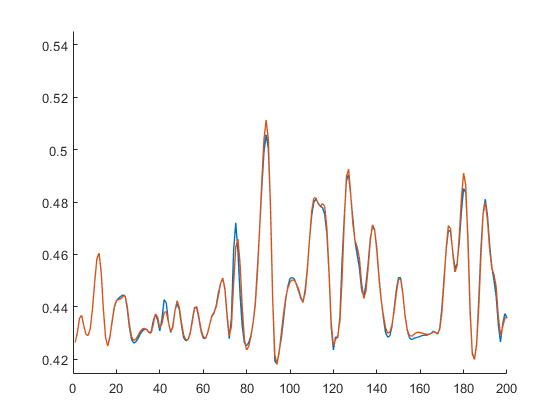

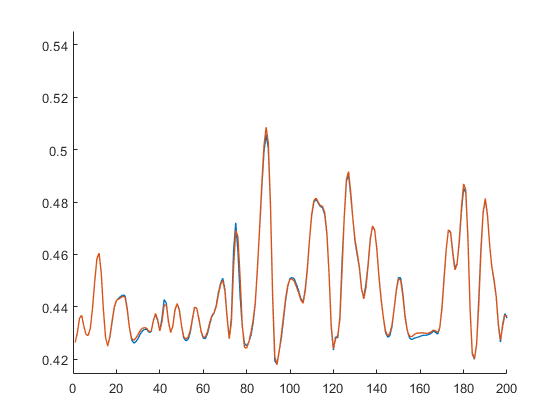

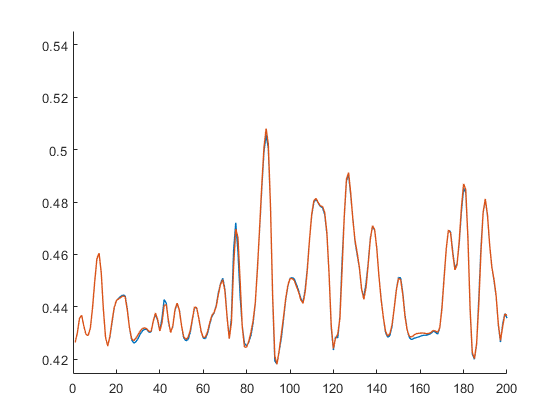

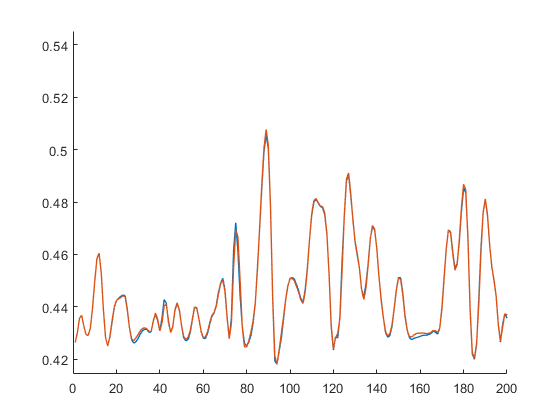

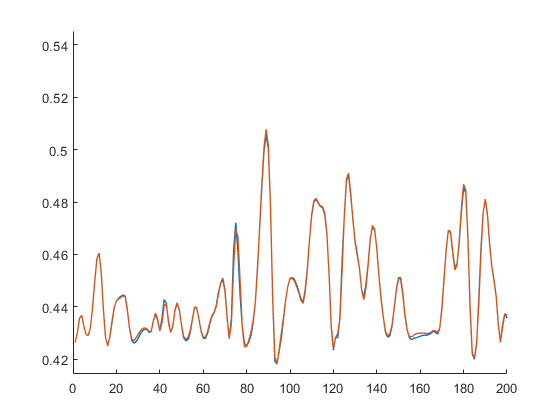

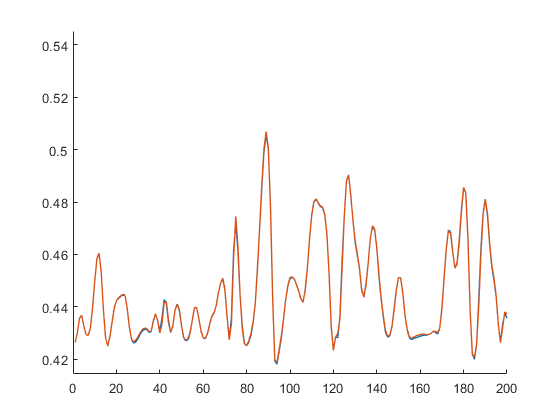

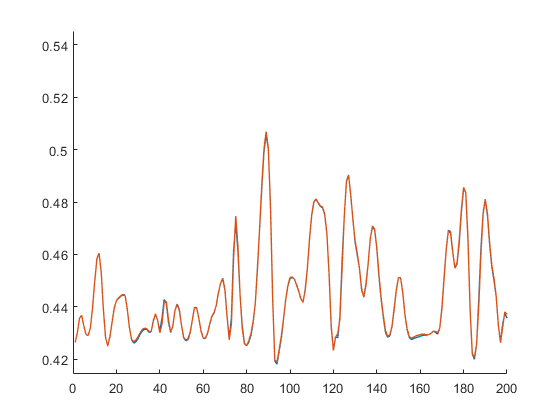

% plot(tinput)
% plot(toutput)

siminputz = tinput;
simoutputz = toutput;
numz = numel(outlags);
for j = 17:1000
simfeaturez = [simoutputz(j-outlags(2:end))' siminputz(j-outlags(2:end))'];
simfeaturez(simfeaturez<0)=0;
simfeaturez(simfeaturez>1)=1;
simoutputz(j) = evalspline(TN,simfeaturez,n,m);
end

figure
hold on
% plot(toutputnoise)
plot(toutput,'Linewidth',1)
plot(simoutputz,'Linewidth',1)
hold off
axis([0 200 -inf inf])


RMSE(period) = sqrt(immse(toutput,simoutputz));
VAF(period) = 1-var(toutput-simoutputz)/var(toutput);
end
toc

Elapsed time is 5.050779 seconds.


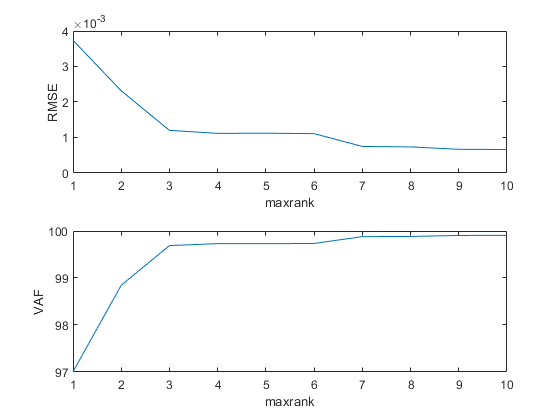

subplot(2,1,1)
plot(1:10,RMSE)
xlabel('maxrank')
ylabel('RMSE')

subplot(2,1,2)
plot(1:10,VAF*100)

xlabel('maxrank')
ylabel('VAF')